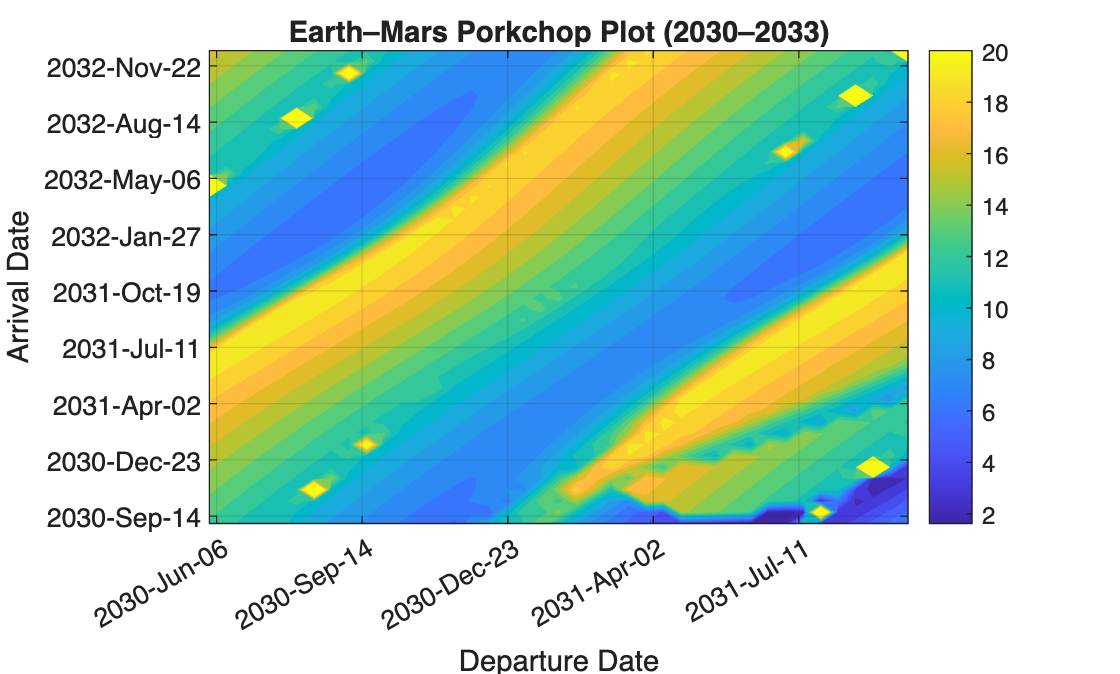

mu_converted = 39.4784176; %AU³/year²

% Create class instances
IT = InterplanetaryTransfers;

% parse data files
[earth_data] = IT.parse_horizon_file('data/earth_data.txt', 'year');
[mars_data] = IT.parse_horizon_file('data/mars_data.txt', 'year');

% Create struct of lambet solver parameters
lsp.mu = mu_converted;
lsp.factors = [1, 2];
lsp.max_iterations = 20;
lsp.tolerance = 1E-8;

IT.create_porkchop_plot(lsp, earth_data, mars_data);